addpath(genpath('./pandemic_model'));

rootpath = pwd;
params = params_default();

intensity_matrix_path = fullfile(rootpath, "output/CEPI_phase_2_exogenous_rental/raw/int_matrix_has_false_1.mat");
load(intensity_matrix_path, "int_matrix");

eps = 1e-10;
intensities_over_time = int_matrix(:, [3:end]);
intensities_long = intensities_over_time(:);
intensities_long_eps = intensities_long;
intensities_long_eps(intensities_long_eps == 0) = eps;

% Define Stata-like colors
stataBlue = [57, 106, 177] / 255;
stataRed = [204, 37, 41] / 255;
stataGreen = [62, 150, 81] / 255;
maroon = [128 0 0] / 255;

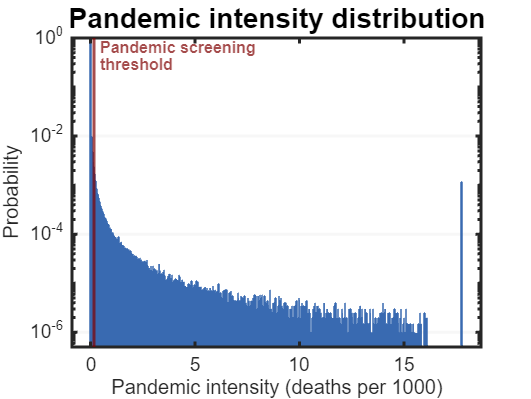

% Create the histogram with normalized probabilities
figure;
h = histogram(intensities_long_eps, 'Normalization', 'probability', 'EdgeColor', stataBlue, 'FaceColor', stataBlue, 'FaceAlpha', 0.7);

% Add labels and title
xlabel('Pandemic intensity (deaths per 1000)', 'FontSize', 10, 'FontName', 'Arial');
ylabel('Probability', 'FontSize', 10, 'FontName', 'Arial');
title('Pandemic intensity distribution', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Arial');

xl = xline(0.16, 'Color', maroon, 'LineWidth', 1.5, ...
    'Label', {'Pandemic screening', 'threshold'}, ...
    'LabelOrientation', 'horizontal', ...
    'FontSize', 8, 'FontName', 'Arial', ...
    'FontWeight', 'Bold', ...
    'LabelVerticalAlignment', 'top');

set(gca, 'YGrid', 'on', 'XGrid', 'off', 'GridLineStyle', '-', 'GridColor', [0.8, 0.8, 0.8]);
set(gca, 'YMinorGrid', 'off');  % Disable minor grid lines

% Set the figure background color to white
set(gcf, 'Color', 'w');

% Set the axes properties
set(gca, 'FontName', 'Arial', 'LineWidth', 1.5, 'YScale', 'log');

% Display the plot
hold off;

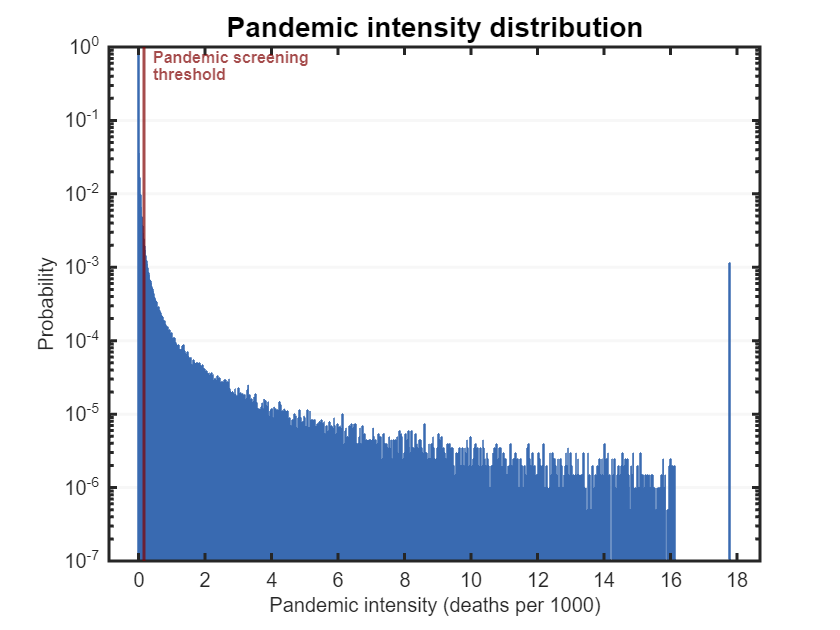

% Save the figure
outpath = fullfile(rootpath, "output/CEPI_phase_2_exogenous_rental/figures/pandemic_intensity_distribution.png");
exportgraphics(gcf, outpath, 'Resolution', 400); % Save as PNG file with 300 dpi